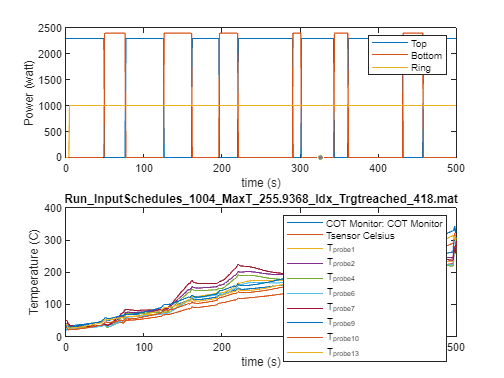

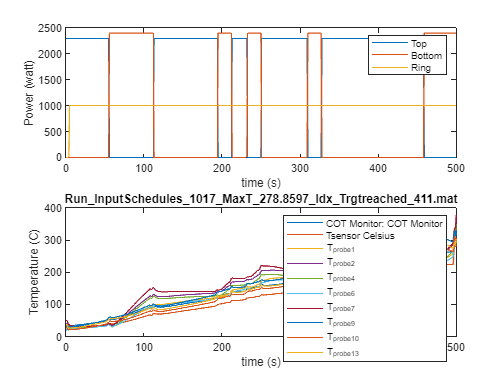

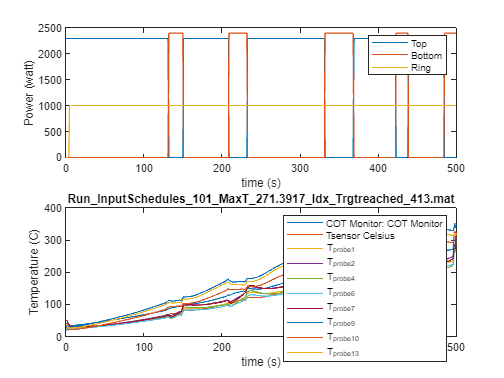

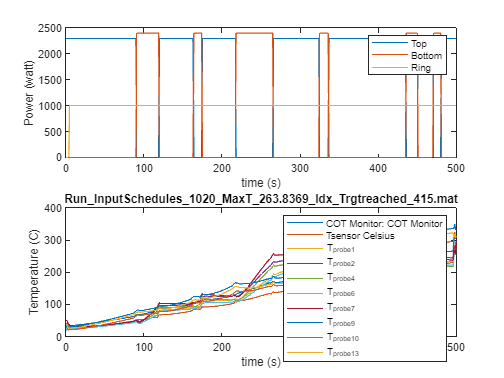

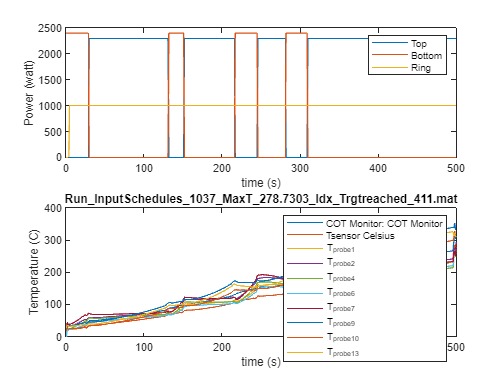

clear all
files=dir('*.mat');
for i=1: 5 %length(files.name)
data=importdata(files(i).name);
figure
subplot(2,1,1)
plot(1:1:500, data.data)
legend('Top', 'Bottom', 'Ring')
xlabel('time (s)')
ylabel('Power (watt)')
subplot(2,1,2)
plot(1:1:500, data.output')
title(files(i).name, 'Interpreter', 'none')
xlabel('time (s)')
ylabel('Temperature (C)')
legend('COT Monitor: COT Monitor', 'Tsensor Celsius', 'T_probe1', 'T_probe2', 'T_probe4', 'T_probe6', 'T_probe7', 'T_probe9','T_probe10','T_probe13')
end

% Save in separate files input / output 
files=dir('*.mat');
for i=1: 500 %length(files.name)
data=importdata(files(i).name);
Z = fullfile('D:\units\thesis\thesis\create_batch_dataset',files(i).name(1:end-4));
if ~exist(Z,'dir')
    mkdir(Z)
    input_table = array2table(data.data);
    input_table.Unique = zeros(height(input_table), 1);
    input_table.Unique(input_table.Var1 == 0 & input_table.Var2 == 2400  & input_table.Var3 == 0 ) = 0;
    input_table.Unique(input_table.Var1 == 0 & input_table.Var2 == 2400  & input_table.Var3 == 1000 ) = 1;
    input_table.Unique(input_table.Var1 == 2300 & input_table.Var2 == 0  & input_table.Var3 == 0 ) = 2;
    input_table.Unique(input_table.Var1 == 2300 & input_table.Var2 == 0  & input_table.Var3 == 1000 ) = 3;
    input_mat = table2array(input_table);
    writematrix(input_mat(:, 4), fullfile(Z, 'actions.csv'))
    writematrix(data.output, fullfile(Z, 'states.csv'))
end

end
traj_probs = ones(500,1);
writematrix(traj_probs, strcat(files(i).name(1:end-3), '_trajprobs.csv'))

% Unique action combos

files=dir('*.mat');
combos = [];
for i=1: 50 %length(files.name)
data=importdata(files(i).name);
combos = [combos; unique(data.data, 'rows')];
end

unique(combos, 'rows')

ans =            0        2400           0
           0        2400        1000
        2300           0           0
        2300           0        1000


% Get params of norm distribution of initial conditions

files=dir('*.mat');
init_conditions = [];
for i=1: 50 %length(files.name)
data=importdata(files(i).name);
init_conditions = [init_conditions; data.output(:,1)];
end

pd = fitdist(init_conditions,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 24.6954   [23.7083, 25.6824]
    sigma = 11.2336   [10.5779, 11.9768]
